clc;
clear ;
close all;

load('DataCube_ELE691_Pruva.mat')
Radar

Radar = struct with fields:
                  Freq: 1.0000e+09
                lambda: 0.3000
             Bandwidth: 10000000
           Pulse_Width: 2.0000e-05
    Frequency_Sampling: 50000000
         Freq_Baseband: 0
                Npulse: 256
                   PRI: 2.0000e-04
                   LFM: [1×1000 double]



figure; plot(1:1000,(Radar.LFM))%LFM before pulse compression

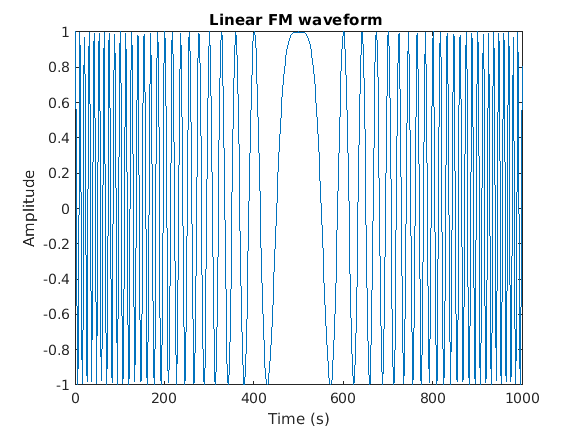

title('Linear FM waveform ')
xlabel('Time (s)')
ylabel('Amplitude')

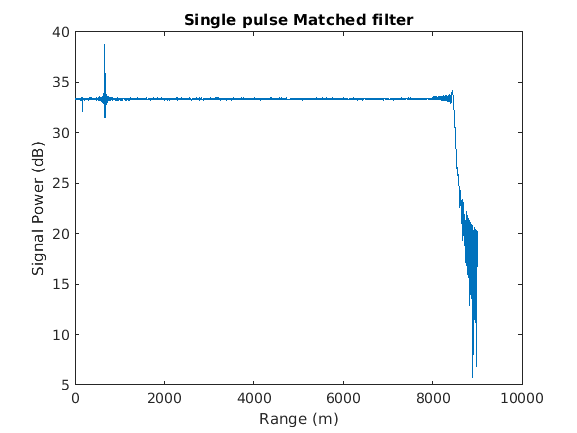

%Matched filtering
C=conj(Radar.LFM); %Matched filter from LFM
for i=1:256
        D(i,:)=conv(Radar_Data(i,:),(fliplr(C))); %Applying Matched filter in fast time
end
D=D(:,(999:1:9998));

figure; plot(10*log10((abs(D(10,:))))) %matched filter single pulse
title('Single pulse Matched filter')
xlabel('Range (m)')
ylabel('Signal Power (dB)')

dopp

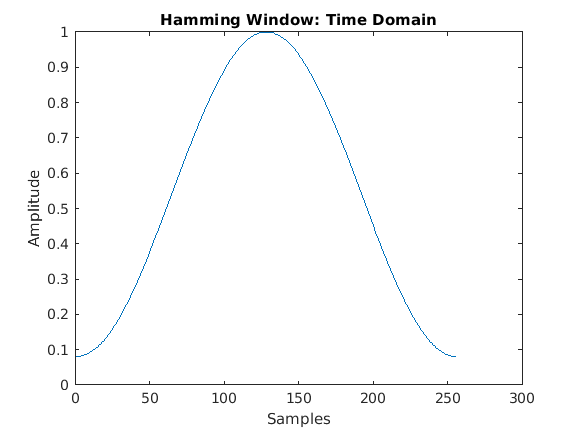

%doppler processing
H=hamming(256); %Windowing
figure; plot(H)
title('Hamming Window: Time Domain')
xlabel('Samples')
ylabel('Amplitude')

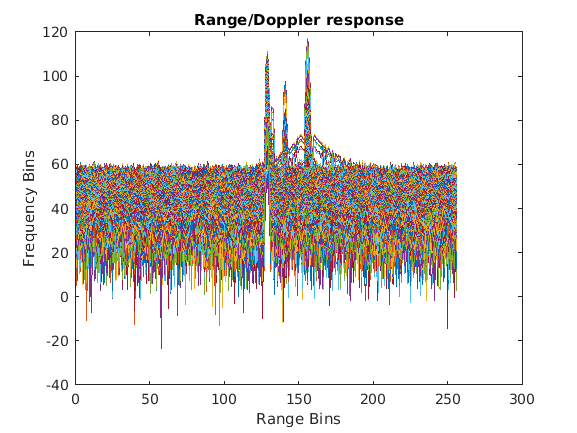


PRF=1/Radar.PRI;
for j=1:9000
   X(:,j)=D(:,j).*H;
    Data(:,j)=fftshift(fft(X(:,j)));
end

figure; plot(20*log10(abs(Data)))
title('Range/Doppler response')
xlabel('Range Bins')
ylabel('Frequency Bins')
zlabel('Signal power dB')

velocity and range

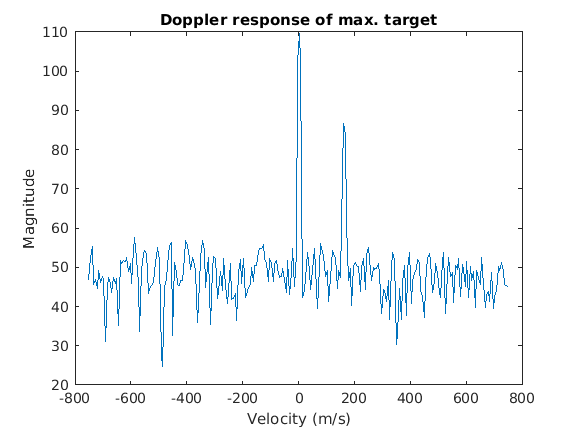

%velocity
V_min=(-PRF/2)*Radar.lambda;
V_max=(PRF/2)*Radar.lambda;
Velocity=V_min:(V_max-V_min)/255:V_max;
figure; plot(Velocity,20*log10(abs(Data(:,700))))
title('Doppler response of max. target')
xlabel('Velocity (m/s)')
ylabel('Magnitude')

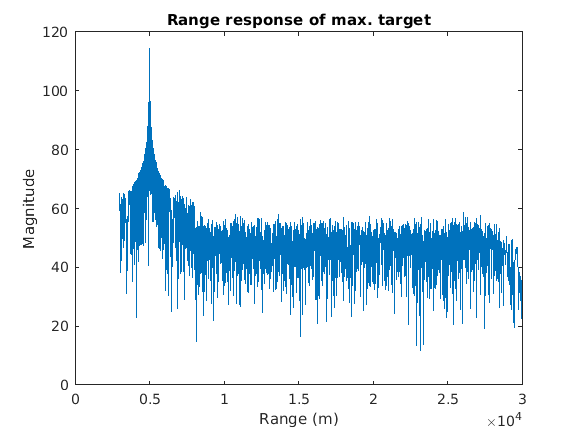


%Range 
c=3e8;
R_min=c*Radar.Pulse_Width/2;
R_max=c*Radar.PRI/2;
Range=R_min:(R_max-R_min)/8999:R_max;
figure; plot(Range,20*log10(abs(Data(157,:))))
title('Range response of max. target')
xlabel('Range (m)')
ylabel('Magnitude')

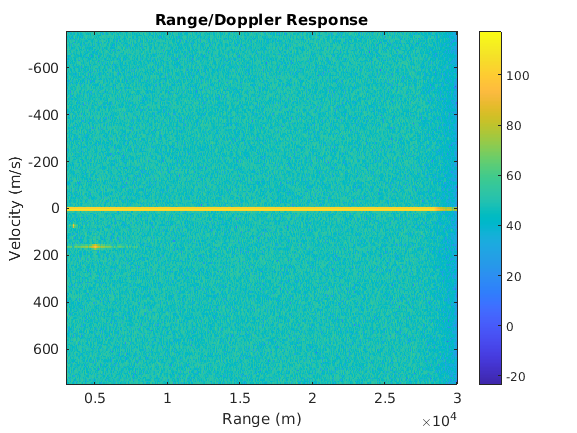


%Surface plot
figure; imagesc(Range,(Velocity),20*log10(abs(Data)))
colorbar;
title('Range/Doppler Response')
xlabel('Range (m)')
ylabel('Velocity (m/s)')
zlabel('Signal power (dB)')